%clc;
clear;
runtime=100

runtime = 100

for count=1:runtime
Road_length  =100*count;
car_number  = count*20;
car(count) =car_number;
acceleration = 6;
deceleration =-6.5;
density(count) = car_number/Road_length;
%initial speed
u = 5;
%time limitis
time =200;
%limit speed
lim = 15;

%repeat loop
for l=1:10
%initial position of car
J = 1:car_number;
A = rand(1,car_number).*Road_length;
x(J,1) =sort(A);
v(J,1)=u;
%minimum distance between cars
x0 = Road_length/car_number;
num = car_number-1;
delT = 0.1;
k = time / delT;
%
average(1) = 0;
t(1) = 0;

for T=2:k
    for J=1:car_number
        if J == car_number
            if J==1
                dis(J,T)= Road_length;
            else
                dis(J,T) = x(1,T-1)-x(J,T-1);
            end
        else
            dis(J,T) = x(J+1,T-1)-x(J,T-1);
        end
        if dis(J,T)<0
            dis(J,T) = Road_length+dis(J,T);
        end
        if dis(J,T) > acceleration * delT
           v(J,T)=v(J,T-1) + acceleration * delT;
        elseif dis(J,T) <= v(J,T-1)
            dis(J,T)=0;
            v(J,T)=0;
        else
           v(J,T)=v(J,T-1)+ deceleration * delT;
        end
        if v(J,T)<0
            v(J,T)=0;
        end
        if v(J,T)>lim
            v(J,T)=lim;
        end
        delta_dis(J,T)=v(J,T)*delT;
        if delta_dis(J,T)>dis(J,T);
            delta_dis(J,T)=dis(J,T);
            v(J,T)=dis(J,T);
        end
        x(J,T)=x(J,T-1)+delta_dis(J,T);
        if x(J,T) > Road_length
           x(J,T)=x(J,T)- Road_length;
        end
    end
      max_speed(T) = max(v(J,T));
      min_speed(T) = min(v(J,T));
      average(T) = sum(v(:,T)) / car_number;
      t(T) = t(T-1) + delT;
end
t(T) = t(T);
x(J,T)=x(J,T);
v(J,T)=v(J,T);
average(T) = average(T);
k_1 = floor(k/2);
d_av = average(1,(k_1):k);
m(l) = mean(d_av);
end
S(count)=std(m);
averagespeed(count) = mean(m);
acc(count)=acceleration;
%percentage
end
S

S =     1.0467    0.8873    0.4033    0.2972    0.3338    0.2285    0.3092    0.2897    0.2330    0.2413    0.2207    0.3588    0.1945    0.3101    0.1386    0.1703    0.1904    0.2098    0.2242    0.3113    0.1981    0.1549    0.1997    0.1271    0.1860    0.1414    0.1436    0.1965    0.1626    0.1498    0.1405    0.1355    0.1961    0.1690    0.0917    0.1807    0.1214    0.1951    0.1275    0.1380    0.1140    0.0829    0.1688    0.1390    0.1611    0.1132    0.2141    0.2579    0.1552    0.1498


averagespeed

averagespeed =     9.8365    9.9535    9.6300    9.7061    9.9778    9.7026    9.7667    9.7244    9.7965    9.6594    9.8495    9.8157    9.8511    9.8210    9.7793    9.8071    9.8244    9.7681    9.8204    9.8428    9.6517    9.8194    9.8117    9.7013    9.8202    9.7516    9.9109    9.8093    9.8124    9.7886    9.8319    9.7182    9.7837    9.7203    9.7873    9.7855    9.8136    9.7904    9.7071    9.7925    9.8159    9.8536    9.7898    9.7840    9.8740    9.7485    9.8314    9.8044    9.7727    9.8109


Saverage=mean(S);
Ave_averagespeed=mean(averagespeed);
for count=1:runtime
percentstd(count)=(S(count)-Saverage)*100;
percentave(count)=(averagespeed(count)-Ave_averagespeed)*100;
end

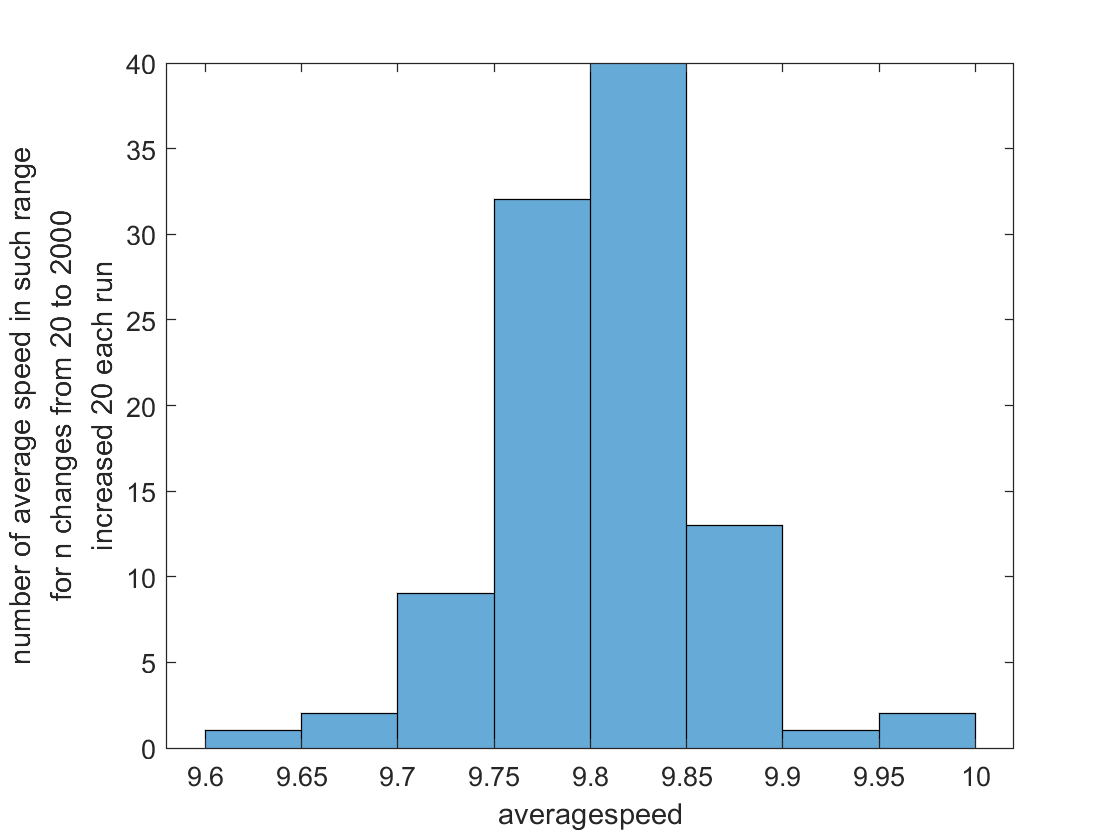

histogram(averagespeed)
xlabel('averagespeed')
ylabel(["number of average speed in such range","for n changes from 20 to 2000","increased 20 each run"])

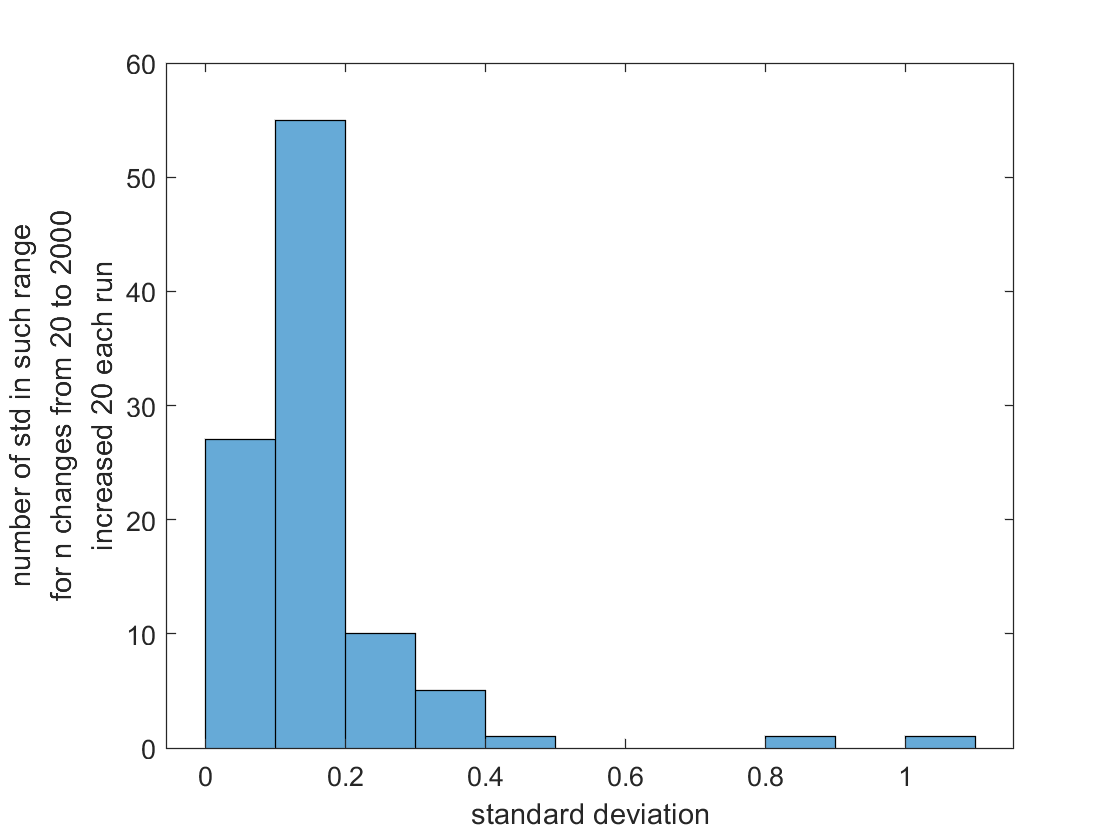

histogram(S)
xlabel('standard deviation')
ylabel(["number of std in such range","for n changes from 20 to 2000","increased 20 each run"])

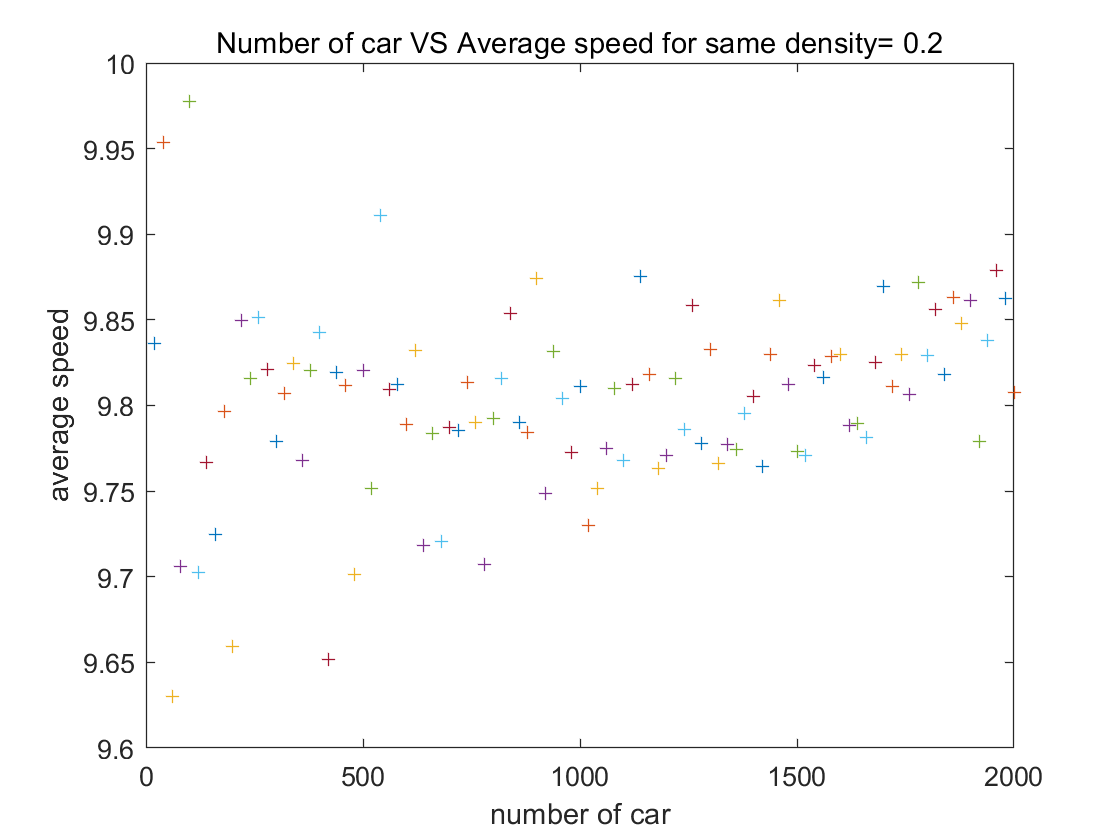

% for i = 1:runtime
%     i2 = i*20;
%     l_str{i} = ['n = ' num2str(i2)];
% end

% Top plot
plot(car(1),averagespeed(1),"+","MarkerSize",5)
hold on
for a=2:runtime
plot(car(a),averagespeed(a),"+","MarkerSize",5)
end
hold off
title("Number of car VS Average speed for same density= 0.2") 
xlabel('number of car')
ylabel('average speed')

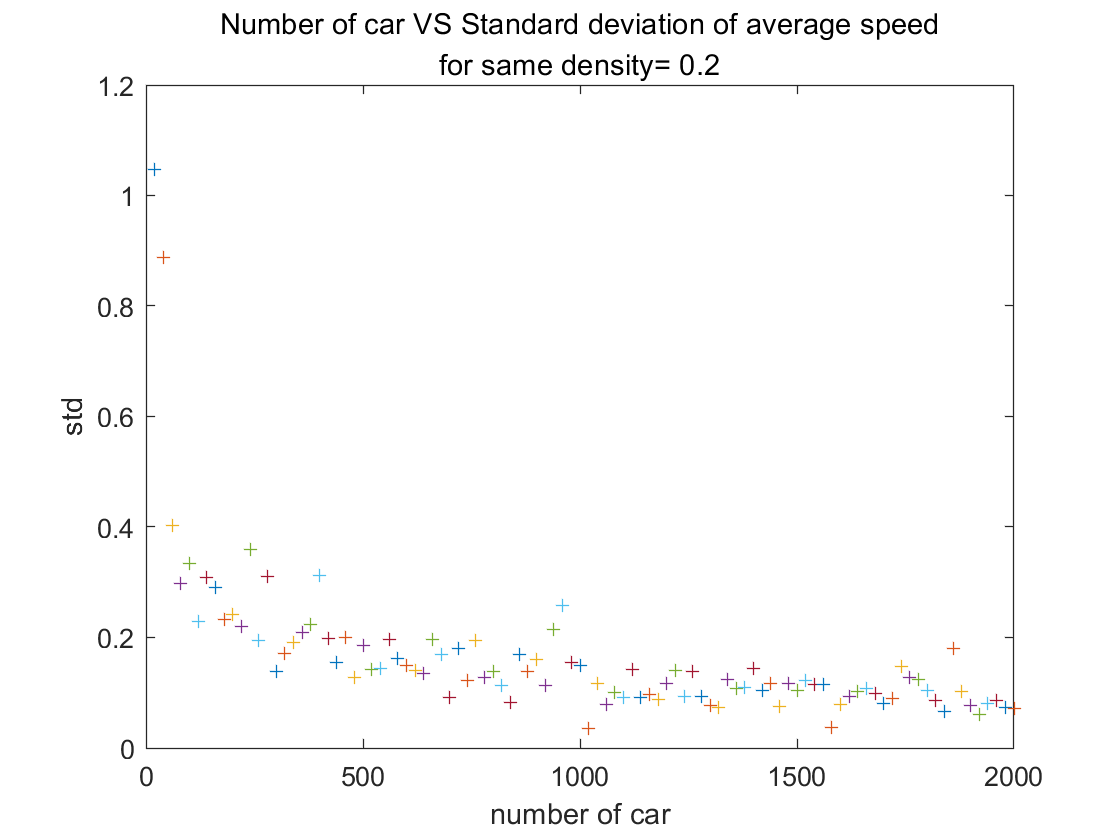

% legend(l_str)
% le = legend(l_str);
% set(le,'fontsize',4,'Location','bestoutside');

% Bottom plot
plot(car(1),S(1),"+","MarkerSize",5)
hold on
for a=2:runtime
plot(car(a),S(a),"+","MarkerSize",5)
end
hold off

title(["Number of car VS Standard deviation of average speed","for same density= 0.2"])
xlabel('number of car')
ylabel('std')

% legend(l_str)
% le = legend(l_str);
% set(le,'fontsize',4,'Location','bestoutside');


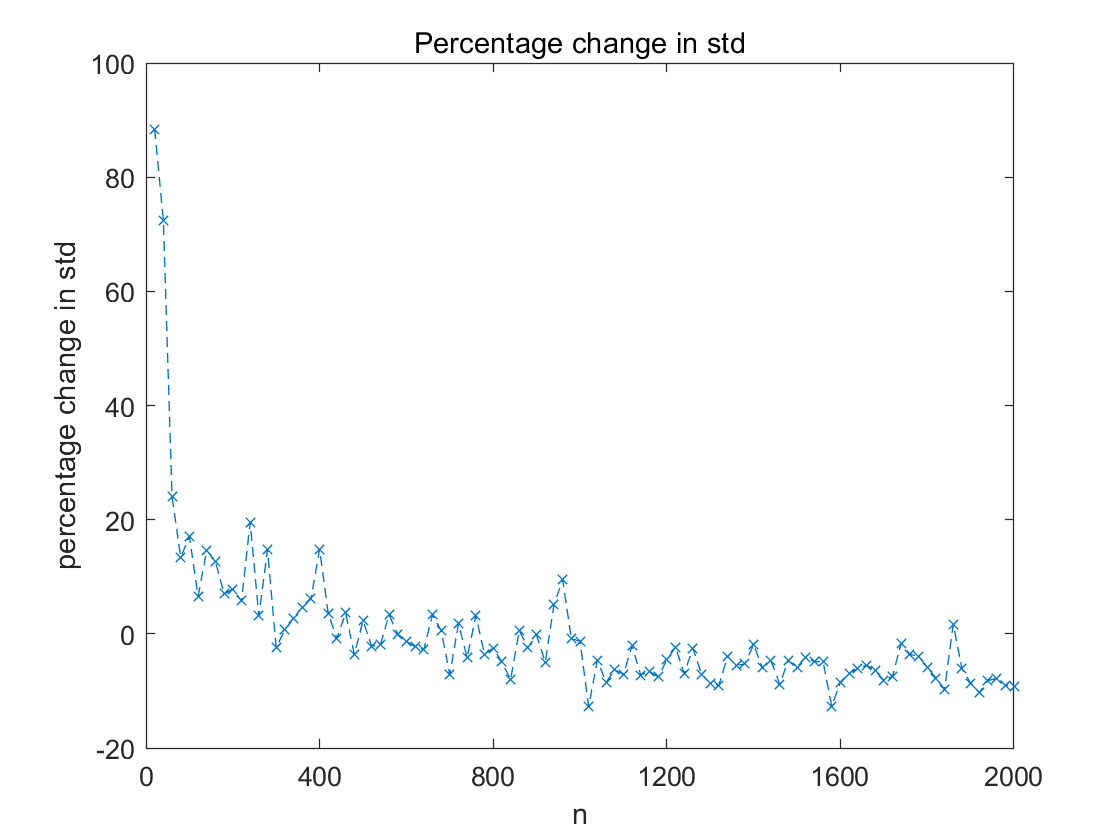


% for i = 1:runtime
%     i2 = i*200;
%     x_str{i} = [num2str(i2)];
% end
plot(percentstd,'--x','MarkerSize',5)
title("Percentage change in std")
xlabel('n')
xticklabels({'0','400','800','1200','1600','2000'});
ylabel('percentage change in std')

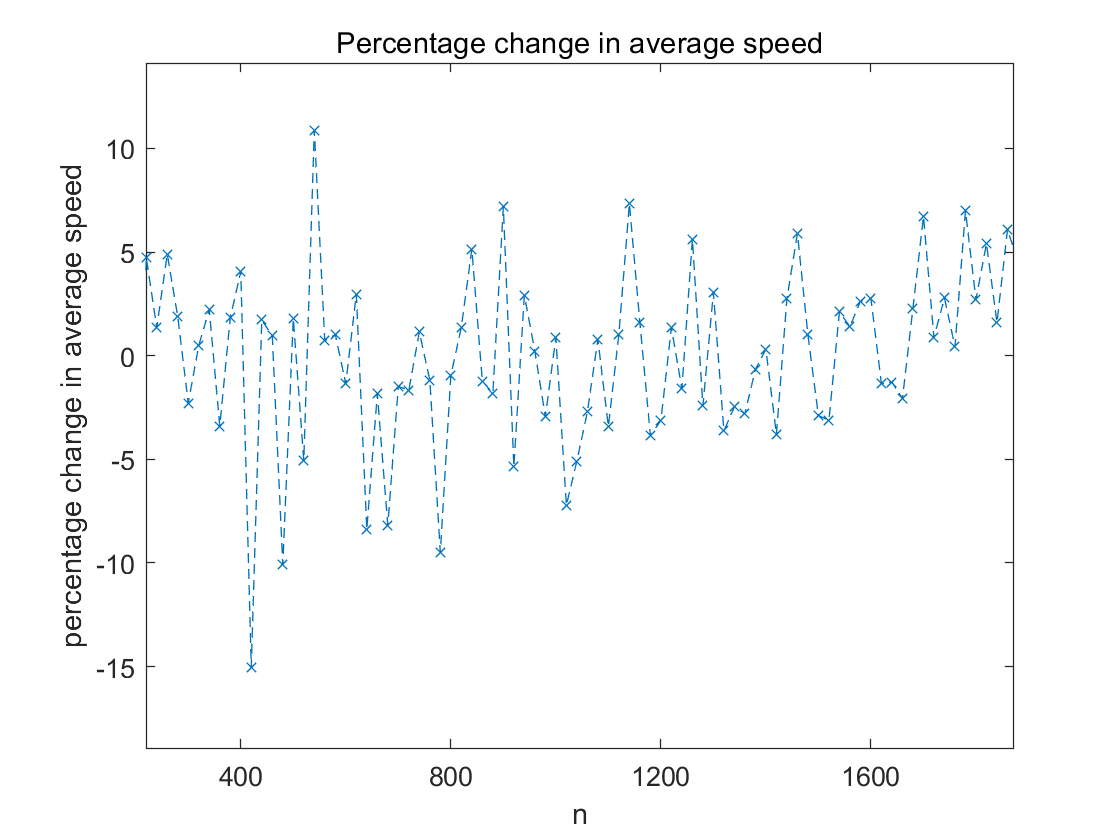

plot(percentave,'--x','MarkerSize',5)
title("Percentage change in average speed")
xlabel('n')
xticklabels({0','400','800','1200','1600','2000'});
ylabel('percentage change in average speed')